# Topic 3 Assignment

Somesh Karthi: 1007935558

## Question 1 

This question has two parts. 

### Question 1 (a)

Construct the $D, \Delta, A$ and $C$ matrix for the **unweighted** graph below, display your answers, and **verify** that $D - \Delta = AA^T$, and $AC = \mathbf{0}$. 

### 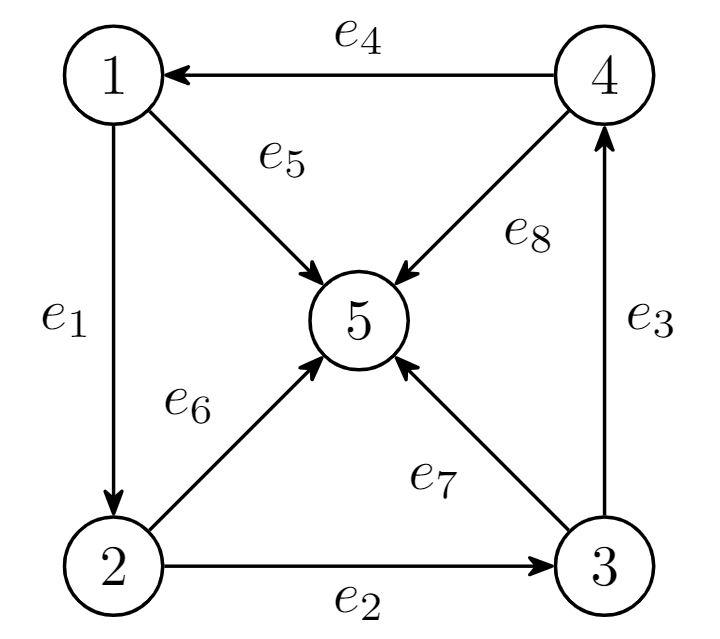

% Your code here
D = [3,0,0,0,0;0,3,0,0,0;0,0,3,0,0;0,0,0,3,0;0,0,0,0,4]

D =      3     0     0     0     0
     0     3     0     0     0
     0     0     3     0     0
     0     0     0     3     0
     0     0     0     0     4


Delta = [0,1,0,1,1;1,0,1,0,1;0,1,0,1,1;1,0,1,0,1;1,1,1,1,0]    

Delta =      0     1     0     1     1
     1     0     1     0     1
     0     1     0     1     1
     1     0     1     0     1
     1     1     1     1     0


A = [1,0,0,-1,1,0,0,0;-1,1,0,0,0,1,0,0;0,-1,1,0,0,0,1,0;0,0,-1,1,0,0,0,1;0,0,0,0,-1,-1,-1,-1]

A =      1     0     0    -1     1     0     0     0
    -1     1     0     0     0     1     0     0
     0    -1     1     0     0     0     1     0
     0     0    -1     1     0     0     0     1
     0     0     0     0    -1    -1    -1    -1


C = [1,0,0,0,-1,1,0,0;0,0,0,1,1,0,0,-1;0,0,1,0,0,0,-1,1;0,1,0,0,0,-1,1,0]'

C =      1     0     0     0
     0     0     0     1
     0     0     1     0
     0     1     0     0
    -1     1     0     0
     1     0     0    -1
     0     0    -1     1
     0    -1     1     0


A*A'

ans =      3    -1     0    -1    -1
    -1     3    -1     0    -1
     0    -1     3    -1    -1
    -1     0    -1     3    -1
    -1    -1    -1    -1     4


D - Delta

ans =      3    -1     0    -1    -1
    -1     3    -1     0    -1
     0    -1     3    -1    -1
    -1     0    -1     3    -1
    -1    -1    -1    -1     4


A*C

ans =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


### Question 1 (b)

How many columns does your $C$ matrix have? You may check by running the `size(C, 2)` command if needed. No justification is necessary. 

% Your code here, if needed

*————————————————————————————————*

*Your answer: It has 4 columns. *

*————————————————————————————————*

### Question 1 (c)

Let $L$ be the matrix $D - \Delta$ or $AA^T$. Compute the smallest $\lambda \geq 0$ such that $\mathrm{det}(L - \lambda I) = 0$.  

(Hint: declare a symbolic variable `lambda`, use the command `eye(N)` to build the $N \times N$ identity matrix, and use the command `det` to find the determinant of a matrix.) 

% Your code here
L = D - Delta

L =      3    -1     0    -1    -1
    -1     3    -1     0    -1
     0    -1     3    -1    -1
    -1     0    -1     3    -1
    -1    -1    -1    -1     4


I = eye(5)

I =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


syms lambda
solutionvector = solve(det(L-lambda*I)==0,lambda)

$$solutionvector = \left(\begin{array}{c} 0\\ 3\\ 3\\ 5\\ 5 \end{array}\right)$$

*————————————————————————————————*

*Your answer: The smallest entry in the solution vector is 0. Therefore, the smallest value for lambda is 0. *

*————————————————————————————————*

Now, make a vector $v$ so that its entries are all$1$'s, and has length equal to the number of rows/columns of $L$. Compute $Lv$, and find the smallest $\lambda \geq 0$ such that $Lv = \lambda v$. 

(Hint: use `ones` and `size` commands.)

% Your code here
v=ones(5)

v =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


Lv = L*v

Lv =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


solve(lambda*v==Lv,lambda)

$$ans = 0$$

What do you notice about the answer to these two questions? 

*————————————————————————————————*

*Your observation*: Lambda is equal to zero in both questions

*————————————————————————————————*

## Question 2 

The answer to the final Exercise this week was that 

$\bar{A}W^{-1}C = \mathbf{0}$, 

Since $\bar{A} = AW$, and $WW^{-1} = I$, and it always holds that $AC = \mathbf{0}$. 

Now, recall the Question 12 in your Written Homework 1. The traffic flow network can be represented using the graph below:

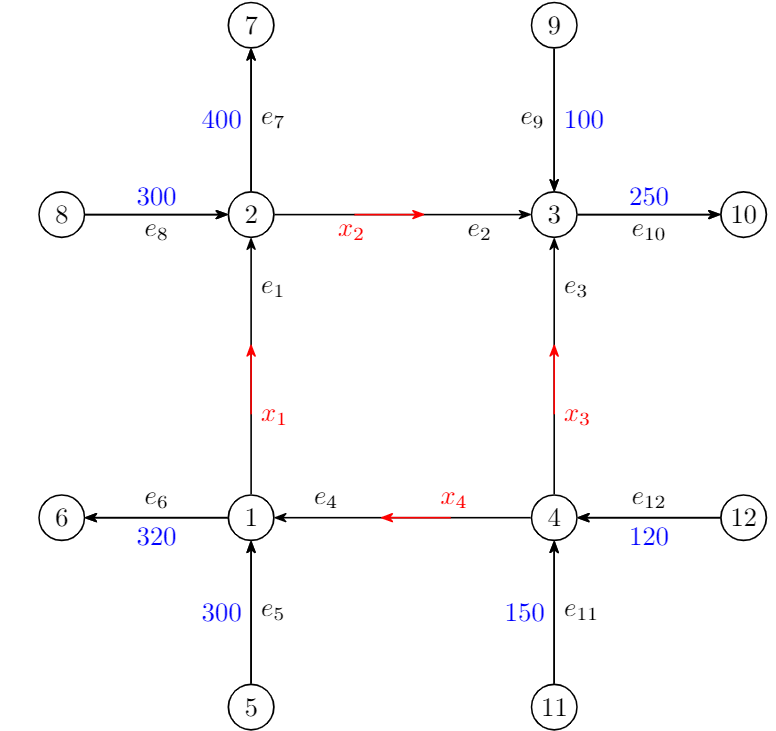

The blue numbers are the **known** number of cars travelling in the direction of the edge; for example, on edge $e_5$, there are 300 cars travelling from node $5$ to node $1$. The **unknowns** are in red: $x_1, x_2, x_3$ and $x_4$. This question has three parts. 

### Question 2 (a)

Construct the unweighted $A$ matrix. Then construct the weighted $A$ matrix in terms variables $x_1, x_2, x_3, x_4$ by first declaring symbolic variables `x1, x2, x3, x4`.

% Your code here
question2A = [1,0,0,-1,-1,1,0,0,0,0,0,0; -1,1,0,0,0,0,1,-1,0,0,0,0; 0,-1,-1,0,0,0,0,0,-1,1,0,0; 0,0,1,1,0,0,0,0,0,0,-1,-1;0,0,0,0,1,0,0,0,0,0,0,0;0,0,0,0,0,-1,0,0,0,0,0,0; 0,0,0,0,0,0,-1,0,0,0,0,0; 0,0,0,0,0,0,0,1,0,0,0,0; 0,0,0,0,0,0,0,0,0,-1,0,0; 0,0,0,0,0,0,0,0,0,0,1,0; 0,0,0,0,0,0,0,0,0,0,0,1]

question2A =      1     0     0    -1    -1     1     0     0     0     0     0     0
    -1     1     0     0     0     0     1    -1     0     0     0     0
     0    -1    -1     0     0     0     0     0    -1     1     0     0
     0     0     1     1     0     0     0     0     0     0    -1    -1
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0    -1     0     0     0     0     0     0
     0     0     0     0     0     0    -1     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0    -1     0     0
     0     0     0     0     0     0     0     0     0     0     1     0


syms x1 x2 x3 x4
question2W = diag([x1,x2,x3,x4,300,320,400,300,100,250,150,120])

$$question2W = \left(\begin{array}{cccccccccccc} x_{1} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & x_{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & x_{3} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & x_{4} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 300 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 320 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 400 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 300 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 100 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 250 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 150 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 120 \end{array}\right)$$

question2Abar = question2A * question2W

$$question2Abar = \left(\begin{array}{cccccccccccc} x_{1} & 0 & 0 & -x_{4} & -300 & 320 & 0 & 0 & 0 & 0 & 0 & 0\\ -x_{1} & x_{2} & 0 & 0 & 0 & 0 & 400 & -300 & 0 & 0 & 0 & 0\\ 0 & -x_{2} & -x_{3} & 0 & 0 & 0 & 0 & 0 & -100 & 250 & 0 & 0\\ 0 & 0 & x_{3} & x_{4} & 0 & 0 & 0 & 0 & 0 & 0 & -150 & -120\\ 0 & 0 & 0 & 0 & 300 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & -320 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -400 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 300 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -250 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 150 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 120 \end{array}\right)$$

What should the size of $A$ and $\bar{A}$ be? 

*————————————————————————————————*

*Your answer: *$12 \times 12$.

*————————————————————————————————*

### Question 2 (b)

How many columns are there in the $C$ matrix? Justify your answer in one sentence. 

*————————————————————————————————*

*Your answer: Since there is only one cycle, there should be one column in the C matrix, as each column in the C matrix represents a cycle. *

*————————————————————————————————*

Construct the edge-cycle incidence matrix $C$. Pick the direction of the cycle(s) such that there are the fewest $-1$ entries in your answer. 

% Your code here
question2C = [1;1;-1;1;0;0;0;0;0;0;0;0]

question2C =      1
     1
    -1
     1
     0
     0
     0
     0
     0
     0


### Question 2 (c)

Using the results from parts (a) and (b), verify the equality $\bar{A}W^{-1}C = \mathbf{0}$ holds on MATLAB. 

(Hint: you only need to figure out how to construct the matrix $W^{-1}$; go back to your the Part 2 Prelab if you don't know how to do this.) 

% Your code here
question2Abar*(inv(question2W)*question2C)

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

Can you find a solution $x_1, x_2, x_3, x_4$ using this equality alone? Why or or not? Justify your answer in one sentence. 

*————————————————————————————————*

*Your answer: No, you can not find a solution for x1, x2, x3, and x4 with this equality alone. This is because equality will always equal to zero regardless of these values. *

*————————————————————————————————*